# **Session 1: Getting started with DataJoint**

Now that you have successfully installed DataJoint. Let's dive into using DataJoint! In this live script, we will:

1. learn what a data pipeline is

2. start designing our first data pipeline based on experiment requirements

3. create the data pipeline in DataJoint

4. insert some data into the pipeline

5. perform basic queries to explore and fetch the data from the pipeline

# So... What is a data pipeline?

If you visit the [documentation for DataJoint](https://docs.datajoint.io/introduction/Data-pipelines.html), we define a data pipeline as follows:

> A data pipeline is a sequence of steps (more generally a directed acyclic graph) with integrated storage at each step. These steps may be thought of as nodes in a graph.

While this is an accurate description, it may not be the most intuitive definition. Put succinctly, a data pipeline is a listing or a "map" of various "things" that you work with in a project, with line connecting things to each other to indicate their dependecies. The "things" in a data pipeline tends to be the *nouns* you find when describing a project. The "things" may include anything from mouse, experimenter, equipment, to experiment session, trial, two-photon scans, electric activities, to receptive fields, neuronal spikes, to figures for a publication! A data pipeline gives you a framework to:

1. define these "things" as tables in which you can store the information about them

2. define the relationships (in particular the dependencies) between the "things"

A data pipeline can then serve as a map that describes everything that goes on in your experiment, capturing what is collected, what is processed, and what is analyzed/computed. A well designed data pipeline not only let's you organize your data well, but can bring out logical clarity to your experiment, and may even bring about new insights by making how everything in your experiment relates together obvious.

Let's go ahead and build together a pipeline from scratch to better understand what a data pipeline is all about.

# **Building our first pipeline: single electrode recording from mouse**

Let's build a pipeline to collect, store and process data and analysis for our hypothetical single electrode recording study in mice. To help us understand the project better, here is a brief description:

- Your lab houses many mice, and each mouse is identified by a unique ID. You also want to keep track of information about each mouse such as their date of birth, and gender.

- As a hard working neuroscientist, you perform experiments every day, sometimes working with more than one mouse in a day! However, on an any given day, a mouse undergoes at most one recording session.

- For each experimental session, you would like to record what mouse you worked with and when you performed the experiment. You would also like to keep track of other helpful information such as the experimental setup you worked on.

- In each experimental session, you record electrical activity from a single neuron. You use recording equipment that produces separate data files for each neuron you recorded.

-  Neuron's activities are recorded as raw traces. Neuron's spikes needs to be detected for further analysis to be performed.

Pipeline design starts by identifying *things* or *entities* in your project. Common entities includes experimental subjects (e.g. mouse), recording sessions, and two-photon scans.

Let's revisit the project description, this time paying special attention to *what *(e.g. nouns) about your experiment. Here I have highlighted some nouns in particular.

-  Your lab houses many **mice**, and each mouse is identified by a unique ID. You also want to keep track of information about each mouse such as their date of birth and gender.

- As a hard working neuroscientist, you perform experiments every day, sometimes working with more than one mouse in a day! However, on an any given day, a mouse undergoes at most one recording session.

- For each **experimental session**, you would like to record what mouse you worked with and when you performed the experiment. You would also like to keep track of other helpful information such as the experimental setup you worked on.

- In each **experimental session**, you record electrical activity from **a single neuron**. You use recording equipment that produces separate data files for each neuron you recorded.

- Neuron's activities are recorded as raw traces. **Neuron's spikes** needs to be detected for further analysis to be performed.

Just by going though the description, we can start to identify *things* or *entities* that we might want to store and represent in our data pipeline:

- mouse

- experimental session

- neuron

- spikes

In DataJoint data pipeline, we represent these* entities* as *tables.* Different *kinds* of entities become distinct tables, and each row of the table is a single example (instance) of the category of entity. 

For example, if we have a `Mouse` table, then each row in the mouse table represents a single mouse!

When constructing such table, we need to figure out what it would take to **uniquely identify** each entry. Let's take the example of the **mouse** and think about what it would take to uniquely identify a mouse.

After some thought, we might conclude that each mouse can be uniquely identified by knowing its **mouse ID** - a unique ID number assigned to each mouse in the lab. The mouse ID is then a column in the table or an **attribute** that can be used to **uniquely identify** each mouse. Such attribute is called the** primary key** of the table.

Once we have successfully identified the primary key of the table, we can now think about what other columns, or **non-primary key attributes** that we would want to include in the table. These are additional **information about each entry in the table that we want to store**.

For the case of mouse, what other information about the mouse you might want to store? Based on the project description, we would probably want to store information such as the mouse's **date of birth** and **gender**.

Now we have an idea on how to represent information about mouse, let's create the table using **DataJoint**!

## Create a schema - house for your tables

Every table lives inside a schema - a logical collection of one or more tables in your pipeline. Your final pipeline may consists of many tables spread across one or more schemas. Let's go ahead and create the first schema to house our table.

We create the schema using `dj.createSchema` function. For this workshop, you are given the database privilege to create any schema **starting with your username followed by a `_` character**. So if your username is `john`, you can make any schema starting with `john_`, such as `john_tutorial`.

% Enter your code, create your own schema here
dj.createSchema

Let's create a schema called `session1`, prefixed by `username_`. Then create a local package `+session1` and link the package to the schema.

Now that we have a schema to place our table into, let's go ahead and define our first table!

## Creating your first table

In DataJoint, you define each table as a class, and provide the table definition (e.g. attribute definitions) as a doc string. The class will inherit from the `dj.Manual` class provided by DataJoint (more on this later). In the MATLAB version of DataJoint, we can create the class by calling the function `dj.new`.

% Enter your code, create your first table!
dj.new

Setting up mym...
No connections open
mym is now ready for use.
 0:  workshop-db.datajoint.io via TCP/IP   Server version 5.5.5-10.1.26-MariaDB
database created
Please select a package folder. Opening UI...


Then we select the type of table we would like to create, in this case, the manual table (M). Then a file callled 'Mouse.m' will automatically be created in the package we created in the last step. Let's edit that file to define the table and create the class.

edit session1.Mouse

/Users/shanshen/Dropbox/Vathes/princeton/princeton-workshop-2019/completed sessions/+session1/Mouse.m already exists


Let's take a look at our brand new table.

session1.Mouse

ans = Object session1.Mouse


<SQL>
CREATE TABLE `shan_workshop_session1`.`mouse` (
`mouse_id` int    NOT NULL COMMENT "unique id of a mouse",
`dob` date  NOT NULL COMMENT "date of birth",
`sex` enum('M', 'F', 'unknown') NOT NULL COMMENT "sex",
PRIMARY KEY (`mouse_id`)
) ENGINE = InnoDB, COMMENT "Experimental mouse"
</SQL>

 :: Experimental mouse ::

0 tuples (3.31 s)


The table was successfully defined, but without any content, the table is not too interesting. Let's go ahead and insert some **mouse** into the table, one at a time using the `insert` method.

Let's insert a mouse with the following information:

- mouse_id: 0

- date of birth: 2018-12-25

- sex: male

% Enter the code to insert a mouse
data = {0, '2018-12-25', 'M'}

data = 1×3 cell array
    {[0]}    {'2018-12-25'}    {'M'}


insert(session1.Mouse, data)

Now let's check the table contents:

session1.Mouse

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'

1 tuples (0.432 s)


We can also insert as a struct:

data = struct('mouse_id', 3, 'dob', '2018-07-04', 'sex', 'F');
insert(session1.Mouse, data)

session1.Mouse

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    3           '2018-07-04'    'F'

2 tuples (0.261 s)


We can also insert mutiple mice together using the `insert` method, passing in a cell array:

data = {
    4 '2017-08-23' 'F'
    5 '2018-08-25' 'F'
    6 '2018-03-19' 'M'
    }

data = 3×3 cell array
    {[4]}    {'2017-08-23'}    {'F'}
    {[5]}    {'2018-08-25'}    {'F'}
    {[6]}    {'2018-03-19'}    {'M'}


% now insert them all at once
insert(session1.Mouse, data)

session1.Mouse

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    3           '2018-07-04'    'F'
    4           '2017-08-23'    'F'
    5           '2018-08-25'    'F'
    6           '2018-03-19'    'M'

5 tuples (0.217 s)


Of course, we can also insert a structure array:

data = [
    struct('mouse_id', 7, 'dob', '2018-07-23', 'sex', 'F')
    struct('mouse_id', 8, 'dob', '2018-09-05', 'sex', 'M')
    struct('mouse_id', 9, 'dob', '2018-07-23', 'sex', 'unknown')
    ]

data = 3×1 struct array with fields:
    mouse_id
    dob
    sex


% now insert them all at once
insert(session1.Mouse, data)

session1.Mouse

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

    0           '2018-12-25'    'M'      
    3           '2018-07-04'    'F'      
    4           '2017-08-23'    'F'      
    5           '2018-08-25'    'F'      
    6           '2018-03-19'    'M'      
    7           '2018-07-23'    'F'      
    8           '2018-09-05'    'M'      
    9           '2018-07-23'    'unknown'

8 tuples (0.25 s)


## Data integrity

DataJoint checks for data integrity, and ensures that you don't insert a duplicate by mistake. Let's try inserting another mouse with `mouse_id: 0` and see what happens!

data = {1, '2019-01-05', 'M'}

data = 1×3 cell array
    {[1]}    {'2019-01-05'}    {'M'}


insert(session1.Mouse, data)

% insert more mice


# Querying data

Often times, you don't want all data but rather work with a **subset of entities** matching specific criteria. 

For this, DataJoint offers very powerful yet intuitive **querying** syntax that lets you select exactly the data you want.

It is also critical to note that the result of any DataJoint query represents a valid entity.

## Restricting by attribute value

The **restriction** operation, `&`, let us specify the criteria to narrow down the table on the left.

**Exact Match**

Mouse with id 0

% Enter your query here
session1.Mouse & 'mouse_id = 0'

All male mice

% Enter your query here
session1.Mouse & 'sex = "M"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'

1 tuples (1.09 s)


All female mice

% Enter your query here
session1.Mouse & 'sex = "F"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    1           '2019-01-05'    'M'
    6           '2018-03-19'    'M'
    8           '2018-09-05'    'M'

4 tuples (0.975 s)


**Inequality**

We can also use inequality in your query to match based on numerical values.

Mouse that is born** after 2018-01-01**

% Enter your query here
session1.Mouse & 'dob > "2018-01-01"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    3           '2018-07-04'    'F'
    4           '2017-08-23'    'F'
    5           '2018-08-25'    'F'
    7           '2018-07-23'    'F'

4 tuples (1.06 s)


Mouse that is **not** male

% Enter your query
session1.Mouse & 'sex != "M"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

    0           '2018-12-25'    'M'      
    1           '2019-01-05'    'M'      
    3           '2018-07-04'    'F'      
    5           '2018-08-25'    'F'      
    6           '2018-03-19'    'M'      
    7           '2018-07-23'    'F'      
    8           '2018-09-05'    'M'      
    9           '2018-07-23'    'unknown'

8 tuples (1.04 s)


**Combining restrictions**

We can easily combine multiple restrictions to narrow down the entities based on multiple attributes.

Let's find all mouse that **is not male** AND **born after 2018-01-01**.

% Enter your query
session1.Mouse & 'sex != "M"' & 'dob > "2018-01-01"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

    3           '2018-07-04'    'F'      
    4           '2017-08-23'    'F'      
    5           '2018-08-25'    'F'      
    7           '2018-07-23'    'F'      
    9           '2018-07-23'    'unknown'

5 tuples (1.24 s)


Result of one query can be used in another query! Let's first find **all female mice** and store the result.

female_mice = session1.Mouse & 'sex = "F"'

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

    3           '2018-07-04'    'F'      
    5           '2018-08-25'    'F'      
    7           '2018-07-23'    'F'      
    9           '2018-07-23'    'unknown'

4 tuples (1.15 s)


among these mice, find ones with **mouse_id > 5**

% Enter your query here
female_mice & 'mouse_id > 5'

female_mice = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    3           '2018-07-04'    'F'
    4           '2017-08-23'    'F'
    5           '2018-08-25'    'F'
    7           '2018-07-23'    'F'

4 tuples (0.972 s)


The result of a query can immediately be used in another query, allowing you to build more complex queries from simpler ones. 

**Restricting with a struct**

All male mice

restr = struct('sex', 'M')

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    7           '2018-07-23'    'F'

1 tuples (0.966 s)


session1.Mouse & restr

# Fetching data

Fetching allows us to retrieve the actual values of certain attributes for all data or a subset of data based on queries.

There are three fetching methods, `fetch`, `fetchn`, and `fetch1`. 

## fetch

Let's see what happens if you fetch the whole table.

% Enter your code here
fetch(session1.Mouse)

restr = struct with fields:
    sex: 'M'


This returns a structure array that only contains the **primary key **of the table.

To also include the specific attributes in the structure array, we can specify the attribute name, for example, the `sex`

% Enter your code here

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    1           '2019-01-05'    'M'
    6           '2018-03-19'    'M'
    8           '2018-09-05'    'M'

4 tuples (0.274 s)


fetch(session1.Mouse, 'sex')

We can also specify multiple attribute names, for example, both the `sex` and `dob`

% Enter your code here
fetch(session1.Mouse, 'sex', 'dob')

ans = 9×1 struct array with fields:
    mouse_id


To include all attributes, we could use `*`

% Enter your code here
fetch(session1.Mouse, '*')

ans = 9×1 struct array with fields:
    mouse_id
    sex


So far, we have been only fetching the whole table.

We can also fetch the data only from the query results.

All male mice

% Enter your query here
male_mice = session1.Mouse & 'sex = "M"'

ans = 9×1 struct array with fields:
    mouse_id
    dob
    sex


Now fetch them!

% Enter your code here
fetch(male_mice)

ans = 9×1 struct array with fields:
    mouse_id
    dob
    sex


or all in one step:

% Enter your code here
fetch(session1.Mouse & 'sex = "M"')

male_mice = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    1           '2019-01-05'    'M'
    6           '2018-03-19'    'M'
    8           '2018-09-05'    'M'

4 tuples (0.295 s)


All the fetching results so far were struct arrays. Are we able to get the data in other formats, such as a scalar, a string, a vector or a cell array?

Yes! `fetch1` and `fetchn` are methods for these purposes.

`fetch1`** and **`fetchn`

Both fetch1 and fetchn could be used to directly fetch the value(s) of one or more attributes. fetch1 works for query results that contains only one entry, and fetchn works on query results of one or more entries. 

For example, get the **sex** for mouse 0, as a string

% Enter your code here
sex_0 = fetch1(session1.Mouse & 'mouse_id = 0', 'sex')

ans = 4×1 struct array with fields:
    mouse_id


Get both the **sex** and **date of birth** for mouse 0, both as strings

% Enter your code here
[sex_0, dob_0] = fetch1(session1.Mouse & 'mouse_id = 0', 'sex', 'dob')

sex_0 = 'M'

Fetch multiple entires (**sex** of **all mice born after "2018-01-01"**) with `fetchn`

% Enter your code here
mice_sex = fetchn(session1.Mouse, 'sex')

sex = 9×1 cell array
    {'M'      }
    {'M'      }
    {'F'      }
    {'F'      }
    {'F'      }
    {'M'      }
    {'F'      }
    {'M'      }
    {'unknown'}


Now let's fetch multiple attributes of these mice: mouse_id, sex, and dob

[mice_ids, mice_sex, mice_dob] = fetchn(session1.Mouse & 'dob > "2018-01-01"', 'mouse_id', 'sex', 'dob')

mice_ids =      0
     1
     3
     5
     6
     7
     8
     9


mice_sex = 8×1 cell array
    {'M'      }
    {'M'      }
    {'F'      }
    {'F'      }
    {'M'      }
    {'F'      }
    {'M'      }
    {'unknown'}


mice_dob = 8×1 cell array
    {'2018-12-25'}
    {'2019-01-05'}
    {'2018-07-04'}
    {'2018-08-25'}
    {'2018-03-19'}
    {'2018-07-23'}
    {'2018-09-05'}
    {'2018-07-23'}


`mice_ids` return as a vector, while `mice_sex` and `mice_dob` are cell arrays. 

`fetchn` also works for one entry, guess what will be returned if we restrict to a single mouse (**mouse_id = 0**)?

% Enter your code here
[mouse_id, mouse_sex, mouse_dob] = fetchn(session1.Mouse & 'mouse_id = 0', 'mouse_id', 'sex', 'dob')

mouse_id = 0

mouse_sex = 1×1 cell array
    {'M'}


mouse_dob = 1×1 cell array
    {'2018-12-25'}


# Working with tables with dependencies

Congratulations! We have successfully created your first table and learned to query and fetch it! We are now ready to tackle and include other **entities** in the project into our data pipeline. 

Let's now take a look at representing an **experimental session**.

As with mouse, we should think about **what information (i.e. attributes) is needed to uniquely identify an experimental session**. Here is the relevant section of the project description:

- As a hard working neuroscientist, you perform experiments every day, sometimes working with **more than one mouse in a day**! However, on an any given day, **a mouse undergoes at most one recording session**.

- For each experimental session, you would like to record **what mouse you worked with** and **when you performed the experiment**. You would also like to keep track of other helpful information such as the **experimental setup** you worked on.

Based on the above, it appears that you need to know:

- the date of the session

- the mouse you recorded from in that session

to uniquely identify a single experimental session.

Thus we will need both **mouse** and a new attribute **session_date** to uniquely identify a single session. 

Remember that a **mouse** is already uniquely identified by its primary key - **mouse_id**. In DataJoint, you can declare that **session** depends on the mouse, and DataJoint will automatically include the mouse's primary key (`mouse_id`) as part of the session's primary key, along side any additional attribute(s) you specificy.

dj.new

You can actually generate the entity relationship diagram (ERD) on the fly by calling `erd` with the schema object

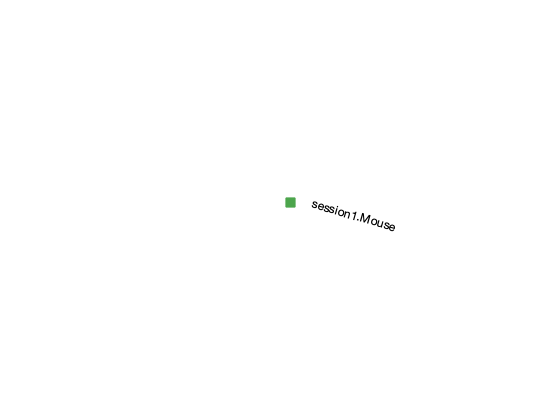

% Enter your code to plot the ERD of the schema
erd session1

Let's try inserting a few sessions manually.

data = struct( ...
    'mouse_id', 0, ...
    'session_date', '2019-02-13', ...
    'experiment_setup', 0, ...
    'experimenter', 'Shan Shen'...
    )

data = struct with fields:
            mouse_id: 0
        session_date: '2019-02-13'
    experiment_setup: 0
        experimenter: 'Shan Shen'


insert(session1.Session, data)


<SQL>
CREATE TABLE `shan_workshop_session1`.`session` (
`mouse_id` int NOT NULL COMMENT "unique id of a mouse",
CONSTRAINT `yMEq9IMs` FOREIGN KEY (`mouse_id`) REFERENCES `shan_workshop_session1`.`mouse` (`mouse_id`) ON UPDATE CASCADE ON DELETE RESTRICT,
`session_date` date    NOT NULL COMMENT "date of the session",
`experiment_setup` int   NOT NULL COMMENT "setup number",
`experimenter` varchar(100) NOT NULL COMMENT "name of the experimenter",
PRIMARY KEY (`mouse_id`,`session_date`)
) ENGINE = InnoDB, COMMENT "Experimental session"
</SQL>



session1.Session

ans = Object session1.Session

 :: Experimental session ::

    MOUSE_ID    SESSION_DATE    experiment_setup    experimenter
    ________    ____________    ________________    ____________

    0           '2019-02-13'    0                   'Shan Shen' 

1 tuples (1.33 s)


Let's insert another session for `mouse_id = 0` but on a different date.

data = struct( ...
    'mouse_id', 0, ...
    'session_date', '2019-02-14', ...
    'experiment_setup', 0, ...
    'experimenter', 'Shan Shen'...
    )

data = struct with fields:
            mouse_id: 0
        session_date: '2019-02-14'
    experiment_setup: 0
        experimenter: 'Shan Shen'


insert(session1.Session, data)


And another session done on the same date but on a different mouse.

data = struct( ...
    'mouse_id', 3, ...
    'session_date', '2019-02-14', ...
    'experiment_setup', 100, ...
    'experimenter', 'Dimitri Yatsenko'...
    )

data = struct with fields:
            mouse_id: 3
        session_date: '2019-02-14'
    experiment_setup: 100
        experimenter: 'Dimitri Yatsenko'



insert(session1.Session, data)
session1.Session

ans = Object session1.Session

 :: Experimental session ::

    MOUSE_ID    SESSION_DATE    experiment_setup       experimenter   
    ________    ____________    ________________    __________________

    0           '2019-02-13'      0                 'Shan Shen'       
    0           '2019-02-14'      0                 'Shan Shen'       
    3           '2019-02-14'    100                 'Dimitri Yatsenko'

3 tuples (0.326 s)


What happens if we try to insert a session for a mouse that doesn't exist?

bad_data = struct( ...
    'mouse_id', 9999, ... % this mouse doesn't exist!
    'session_date', '2019-02-12', ...
    'experiment_setup', 0, ...
    'experimenter', 'Shan Shen' ...
    )

bad_data = struct with fields:
            mouse_id: 9999
        session_date: '2019-02-12'
    experiment_setup: 0
        experimenter: 'Shan Shen'


insert(session1.Session, bad_data)

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    3           '2018-07-04'    'F'

2 tuples (0.486 s)


# Querying with multiple tables

Now we have two tables, we can perform more exciting queries!

## Restricting by other table

All mouse that has a session

% Enter your code here
session1.Mouse & session1.Session

male_mice = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    1           '2019-01-05'    'M'
    6           '2018-03-19'    'M'
    8           '2018-09-05'    'M'

4 tuples (0.215 s)


## Combining restrictions

Find sessions performed on a** male** mouse

% Enter your code here
male_mice = session1.Mouse & 'sex = "M"'

ans = Object session1.Session

 :: Experimental session ::

    MOUSE_ID    SESSION_DATE    experiment_setup    experimenter
    ________    ____________    ________________    ____________

    0           '2019-02-13'    0                   'Shan Shen' 
    0           '2019-02-14'    0                   'Shan Shen' 

2 tuples (0.273 s)


Restrict Session with male mice

% Enter your code here
session1.Session & male_mice

ans = Object session1.Session

 :: Experimental session ::

    MOUSE_ID    SESSION_DATE    experiment_setup    experimenter
    ________    ____________    ________________    ____________

    0           '2019-02-13'    0                   'Shan Shen' 
    0           '2019-02-14'    0                   'Shan Shen' 

2 tuples (0.459 s)


Or we do it in one step

session1.Session & (session1.Mouse & 'sex = "M"')

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

    0           '2018-12-25'    'M'
    3           '2018-07-04'    'F'

2 tuples (0.284 s)


Give me all mice that have had an experimental session **done on or before 2019-02-13**

% Enter your code here
session1.Mouse & (session1.Session & 'session_date <= 2019-02-13')

nothing to delete


## Deleting entries

Now we have a good idea on how to restrict table entries, this is a good time to introduce how to **delete** entries from a table.

To delete a specific entry, you restrict the table down to the target entry, for example **mouse_id = 8**, and call `del` method.

% Enter your code here
del(session1.Mouse & 'mouse_id = 8')

ans = Object session1.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

    0           '2018-12-25'    'M'      
    1           '2019-01-05'    'M'      
    3           '2018-07-04'    'F'      
    4           '2017-08-23'    'F'      
    5           '2018-08-25'    'F'      
    6           '2018-03-19'    'M'      
    7           '2018-07-23'    'F'      
    9           '2018-07-23'    'unknown'

8 tuples (0.283 s)


session1.Session


ABOUT TO DELETE:
       8 tuples from `shan_workshop_session1`.`mouse` (manual)
       3 tuples from `shan_workshop_session1`.`session` (manual)

delete canceled


Calling `del` method on an *unrestricted* table will attempt to delete the whole table!

del(session1.Mouse)

ans = Object dj.internal.GeneralRelvar

    MOUSE_ID    SESSION_DATE        dob         sex    experiment_setup       experimenter   
    ________    ____________    ____________    ___    ________________    __________________

    0           '2019-02-13'    '2018-12-25'    'M'      0                 'Shan Shen'       
    0           '2019-02-14'    '2018-12-25'    'M'      0                 'Shan Shen'       
    3           '2019-02-14'    '2018-07-04'    'F'    100                 'Dimitri Yatsenko'

3 tuples (0.752 s)


Notice that when you try to delete all `Mouse`, `del` also warned that `Session` entries will get deleted! 

DataJoint understands and keeps track of dependencies such that **no dependent entries will be left orphaned**. The `del` operations automatically **cascades down** the dependency to ensure data integrity. We will revisit this point in the next session.

## Joining tables

Sometimes you want to see information from multiple tables combined together to be viewed (and queried!) simultaneously. You can do this using the** join **`*` operator.

For example, let's** join** the table **Mouse** and **Session**

% Enter your code here
session1.Mouse * session1.Session

ans = Object dj.internal.GeneralRelvar

    MOUSE_ID    SESSION_DATE        dob         sex    experiment_setup    experimenter
    ________    ____________    ____________    ___    ________________    ____________

    0           '2019-02-13'    '2018-12-25'    'M'    0                   'Shan Shen' 
    0           '2019-02-14'    '2018-12-25'    'M'    0                   'Shan Shen' 

2 tuples (0.241 s)


Here each row represents a unique (and valid!) combination of a mouse and a session.

The combined table can be queried using any of the attributes (columns) present in the joined tables, for sample, get all sessions performed on** male mice** and performed by** Shan Shen**

% Enter your code here
session1.Mouse * session1.Session & 'sex = "M"' & 'experimenter = "Shan Shen"'

# Summary

Congratulations! You have successfully created your first DatJoint pipeline, using dependencies to establish the link between the tables. You have also learned to query and fetch the data.

In the next session, we are going to extend our data pipeline with tables to represent **imported data** and define new tables to **compute and hold analysis results**.